**Handwritten Digit Recognition using K-Nearest Neighbors (KNN) Classifier**

Joseph Park

College of the Sequoias

CSCI 20: MATLAB Programming

Professor Dillon Allen

December 8, 2024

**Introduction**

Our ability to recognize objects is a complex neurological process we often take for granted when envisioning computer intelligence. When we look at an object, visual data from our eyes is transmitted to the brain, where the shapes and dimensions of the object are analyzed. This information is then matched against patterns stored in our cerebral cortex, which have been put there from our life experiences. The brain essentially "templates" new visual input against its memory to achieve recognition (at least this is a simple analogy describing our brain processes, not the entire picture).

Mimicking this cognitive process is central to digit recognition in computers. While complex algorithms can identify intricate objects, digit recognition can often be accomplished with simpler approaches, such as the K-Nearest Neighbors (KNN) classifier. KNN is a non-parametric, supervised learning algorithm that classifies data points based on their proximity to one another. It is popular for its simplicity, requiring only the tuning of a single parameter, K, and the computation of distances between data points.

This project demonstrates the effectiveness of KNN in classifying handwritten digits using the MNIST dataset, a dataset consisting of 10,000 grayscale images of digits ranging from 0 to 9. Each image is represented as a 28x28 pixel array, flattened into a vector of 784 features. Using KNN, we aim to identify these digits based on their visual patterns.

**How KNN Works**

Imagine a dataset containing the weights and mileages of vehicles. If plotted on a 2D grid, these points might reveal clusters representing different types of vehicles, such as cars and trucks. If tasked with classifying a specific combination of weight and mileage, we might use the intuition that similar objects are located near each other. For example, trucks are generally heavier and have worse mileage than cars (although cases like sports cars or SUVs break this imagery).

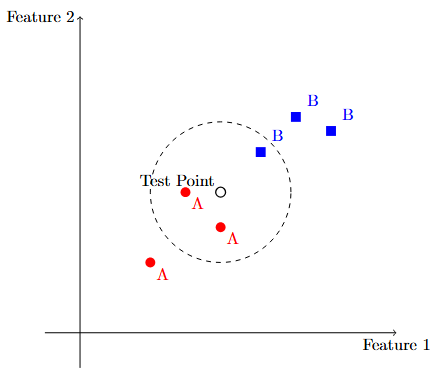

In KNN, a test point's classification is determined by its "neighbors" within a defined radius. Consider a test point surrounded by a dashed circle representing its K-nearest neighbors. If K=3, there are 2 red points (representing cars) and 1 blue point (representing trucks). KNN would classify the test point as a car.

Mathematically, we calculate the Euclidean distance between the test point and every other point in the dataset. We then select the K closest neighbors. The test point is classified based on the majority (mode) of these neighbors.

**Applying KNN to Digit Recognition**

In digit recognition, KNN operates similarly. Using the MNIST dataset, we treat each 28x28 image of a digit as a 784-dimensional data point. For a given test image, it computes the distance to every image in the training set, then based on the majority of the K closest neighbors, KNN assigns a label, or classifies, the image.

Below is code demonstrating the use of KNN to classify handwritten digits:

clear, clc, close all;

% {1} Importing images and define matrices.
trainingSet = readtable('./DigitDataset/digitTrain.csv');
testingSet = readtable('./DigitDataset/digitTest.csv');
train_x = [];
train_y = [];
test_x = [];
test_y = [];

% {2} Loop through images and append each image as a column vector into
% matrices. Image values are stored in `x` matrices while their digit
% values are placed into `y` matrices.
for i = 1:height(trainingSet)
    img_name = trainingSet{i,1}{1};
    img_digit = trainingSet{i,2};
    img = imread(['DigitDataset/' num2str(img_digit) '/' img_name]);
    train_x = [train_x, img(:)];
    train_y = [train_y, img_digit];

    img_name = testingSet{i,1}{1};
    img_digit = testingSet{i,2};
    img = imread(['DigitDataset/' num2str(img_digit) '/' img_name]);
    test_x = [test_x, img(:)];
    test_y = [test_y, img_digit];
end

% {3} Normalize values in the `x` matrices.
train_x = double(train_x) / 255;
test_x = double(test_x) / 255;

% {4} Run the KNN using K=5 and store predictions in `pred_y`.
pred_y = knn(train_x, train_y, test_x, 5);

% {5} Calculate accuracy of the model by comparing `pred_y` to `test_y`.
acc = accuracy(pred_y, test_y);
disp(acc);

    0.9716



This KNN model is very good at classifying handwritten digits, achieving an accuracy of approximately 97%. On a test set of 5,000 images, it correctly predicted the digits for roughly 4,850 of them.

Below, we display examples of both correct and incorrect predictions made by the classifier:

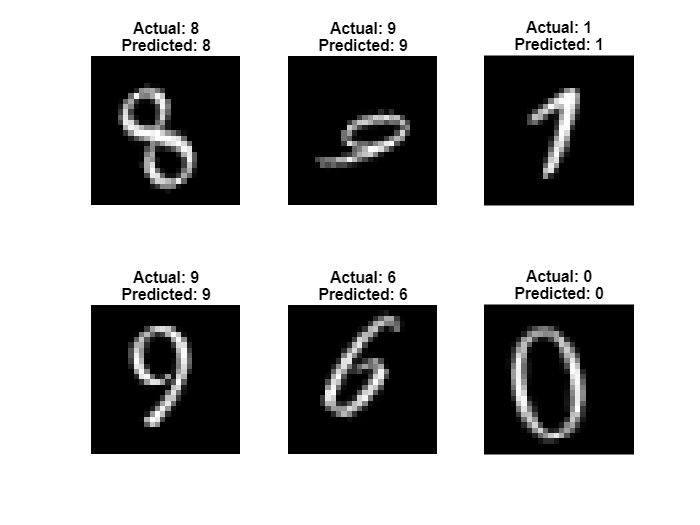

% Find indices of correct predictions
correctIndices = find(pred_y == test_y);
numCorrect = min(6, length(correctIndices));
selectedIndices = correctIndices(randperm(length(correctIndices), numCorrect));

figure;
rows = 2;
cols = ceil(numCorrect / rows);

for i = 1:numCorrect
    subplot(rows, cols, i);
    img = reshape(test_x(:, selectedIndices(i)), [28, 28]);
    imshow(img, []);
    title({['Actual: ', num2str(test_y(selectedIndices(i)))], ...
           ['Predicted: ', num2str(pred_y(selectedIndices(i)))]});
end

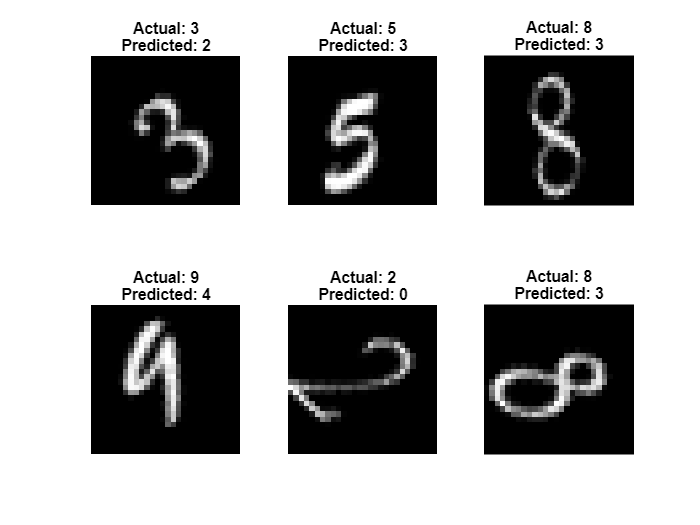

% Find indices of incorrect predictions
incorrectIndices = find(pred_y ~= test_y);
numIncorrect = min(6, length(incorrectIndices));
selectedIndices = incorrectIndices(randperm(length(incorrectIndices), numIncorrect));

figure;
rows = 2;
cols = ceil(numIncorrect / rows);

for i = 1:numIncorrect
    subplot(rows, cols, i);
    img = reshape(test_x(:, selectedIndices(i)), [28, 28]);
    imshow(img, []);
    title({['Actual: ', num2str(test_y(selectedIndices(i)))], ...
           ['Predicted: ', num2str(pred_y(selectedIndices(i)))]});
end

**Conclusion**

Even with a simple algorithm and the semi-challenging task of digit identification, Occam's Razor held true: the simplest solution was sufficient. The KNN classifier achieved an impressive 97% accuracy on the test images which is a remarkable result for such a straightforward approach.

While this outcome highlights the power of KNN, this project does not implement a proper validation process to ensure bias is controlled; a standard validation process includes selecting the best K and randomizing the data used for training and testing. If creating the best possible model for this task were the goal, we should go through these steps to ensure the model's performance is not biased toward a specific dataset split and that it generalizes well to new data.

**Functions**

% Function: KNN
%   Inputs: train_x: Matrix of image vectors used to train the model.
%           train_y: Row vector of pre-classified digits.
%           test_x: Matrix of image vectors used to calculate distances.
%           k: User defined parameter to indicate K.
%   Output: pred_y: Row vector of KNN classified digits.
function pred_y = knn(train_x, train_y, test_x, k)
    pred_y = [];
    for i = 1:length(test_x)
        distances = [];
        neighboringDigits = [];
        test = repmat(test_x(i),1,5000);
        distances = sqrt(sum((train_x - test_x(:, i)).^2, 1));
        [distanceMatrix, distanceIndex] = sort(distances);
        for j = 1:k
            neighboringDigits = [neighboringDigits, train_y(distanceIndex(j))];
        end
        pred_y = [pred_y, mode(neighboringDigits)];
    end
end

% Function: Accuracy
%   Inputs: pred_y: Row vector of the predicted digits.
%           test_y: Actual digits of the images used in test.
%   Ouput: acc: Accuracy calculated by (correct / total).
function acc = accuracy(pred_y, test_y)
    acc = sum(pred_y == test_y) / length(test_y);
end